# Perceptron Algorithm on Example Data

The perceptron learning algorithm is a method that tries to find a sperating hyperplane in classification problems. Given $x_i\in\mathbb{R}^N$ and $y_i\in\{-1,1\}$ we are looking for a hyperplane $\mathcal{H} = \{x\in \mathbb{R}^N |x\beta^T +\beta_0 = 0\}$ where points $x_i$ fall on one side of $\mathcal{H}$determined by the value of $y_i$. When the data is seperable, i.e. such a hyperplane exists, then the algorythm is guaranteed to converge to a valid hyperplane. However the number of steps can be very large and depends on how seperated the data is, the more sperated the faster it converges. Also, if the data is not serperated then the algorithm will not converge and in fact it is hard to detect that convergence will not happen.

In this experiment we purposefully create serpated data and apply the algorithm to finding a seperating hyperplane.

### Setting up the parameters of the experiment

DimensionOfSpace        =    2;
NumberOfTrainSamples    =  5000;
NumberOfTestSamples     = 10000;

### Generating the data for the experiment

We select a random line in the N-dimensional space that we will use for comparing against, this is the true line. We then generate a given amount of random points in this space for our training and testing data. We then compare all of our generated data to our true line, we use this to classify the data.

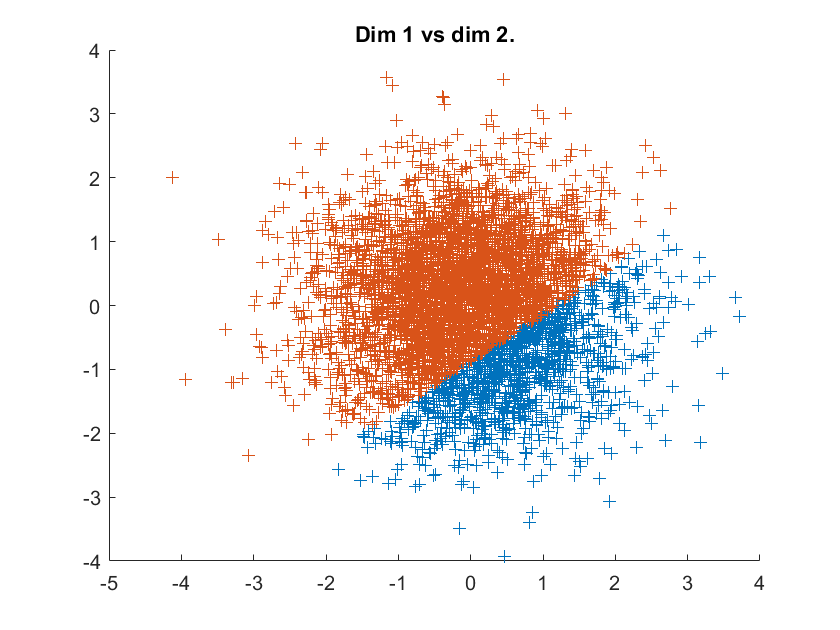

% Setup the rng for repeatability
Helpers.SetupRNG()

% Generate the data and plot it.
[trainData,testData,actualLine] = iGetTrainAndTestData(DimensionOfSpace,NumberOfTrainSamples,NumberOfTestSamples);
actualLine = actualLine/norm(actualLine);
iPlotData(trainData)

### Training

Here we train the model on our trainData using the perceptron learning algorithm. We do this as follows, choose a random line $\beta\in\mathbb{R}^{N+1}$, then for each training point $x_i$ with classification $y_i$ we evaluate the classification by $\beta$ as $sign(x_i\beta^T)$. If this matches with the classification then we do not modify $\beta$, however if it does not match then we update $\beta$ to $\beta + y_ix_i$. We repeat this process of updaing $\beta$ until either all training points are correctly classified or we have gone over a time limit.

[learntLine,models] = trainModel(trainData);

### Testing

Here we test the model on our testData. We do this by applying the classification of each point using our learntLine and comparing to the given class. We can then determin the error of this model, and the difference between the actual model.

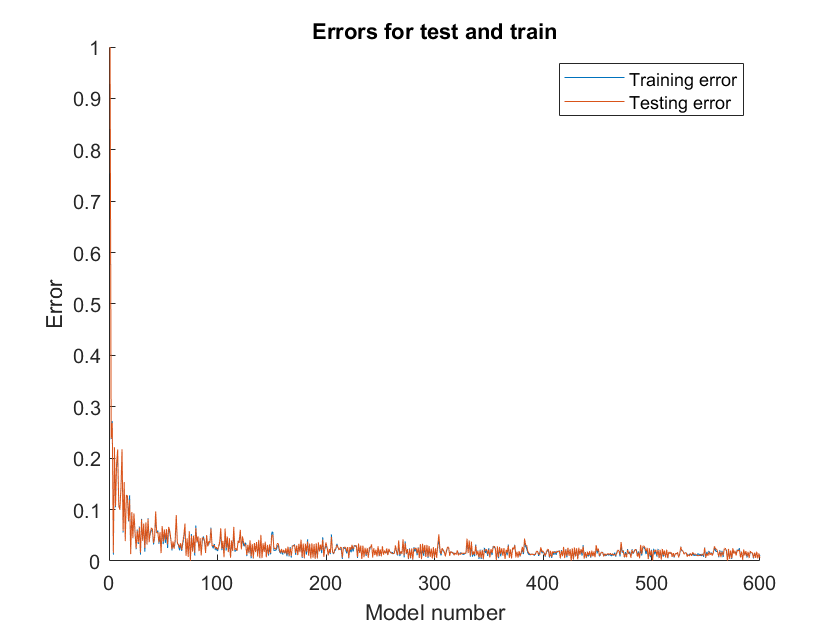

trainErrors = iGetAllErrors(models,trainData);
testErrors  = iGetAllErrors(models,testData);
iPlotErrors(trainErrors,testErrors)

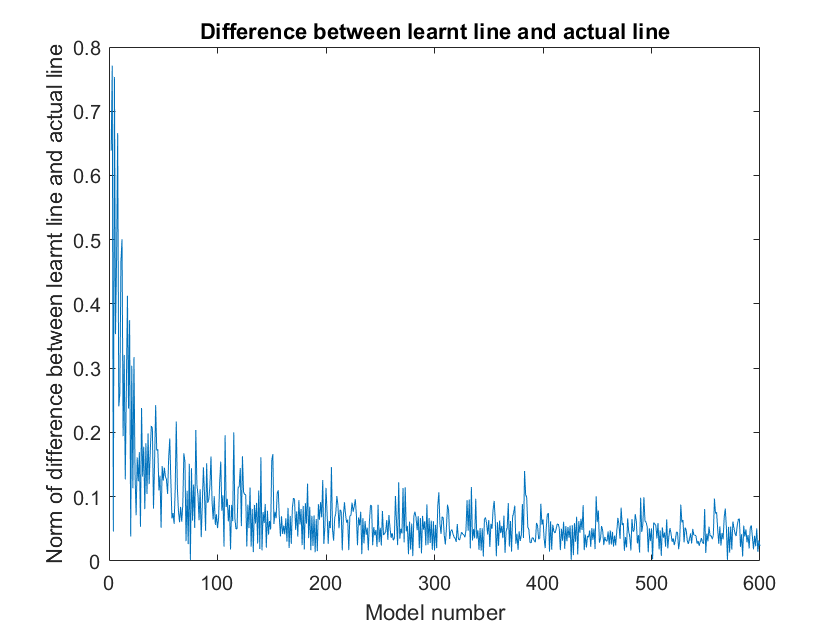

iPlotLineDifferences(models,actualLine)

### Functions

#### Data generation functions

function coefficients = iGenerateSeperatingLine(DimensionOfSpace)
% Generates the coefficients of a random line in an N-dimensional space.
numDimsNeeded = DimensionOfSpace + 1;
coefficients  = randn(1,numDimsNeeded);
end

function [unclassifiedPoints,classification] = iGenerateDataFromLine(DimensionOfSpace,numberOfPoints,line)
% Generates random data in an N-dimensional space and classifies according
% to being above or below the given line.
unclassifiedPoints = randn(numberOfPoints,DimensionOfSpace);
unclassifiedPoints = [ones(numberOfPoints,1),unclassifiedPoints];
values = unclassifiedPoints * line';
classification = sign(values);
end

function [trainData,testData,actualLine] = iGetTrainAndTestData(DimensionOfSpace,NumberOfTrainSamples,NumberOfTestSamples)
% Generates a line in the given space and random data for training and
% testing according to this line.
actualLine = iGenerateSeperatingLine(DimensionOfSpace);
[trainPoints,trainClassification] = iGenerateDataFromLine(DimensionOfSpace,NumberOfTrainSamples,actualLine);
[testPoints,testClassification]   = iGenerateDataFromLine(DimensionOfSpace,NumberOfTestSamples,actualLine);
trainData = {trainPoints,trainClassification};
testData  = {testPoints,testClassification};
end

#### Training functions

function [learntLine,models] = trainModel(data)
% Train a model on the data.

% Get the data and generate a guessed line.
[points,classification]     = data{:};
[numberOfPoints,dimOfSpace] = size(points);
learntLine                  = zeros(1,dimOfSpace);

% While not all points are classified correctly or the time has gone too
% long apply the algorythm and update the line.
classificationNumber = 0;
i = 1;
models = [learntLine];
tic;
while classificationNumber < numberOfPoints && toc < 2
    point = points(i,:);
    class = classification(i);
    [learntLine,classificationNumber] = iUpdateLineFromPoint(point,class,learntLine,classificationNumber);
    models = [models;learntLine];
    i = mod(i,numberOfPoints) + 1;
end

% Normalize the vector.
learntLine = learntLine/norm(learntLine);
end

function [learntLine,classificationNumber] = iUpdateLineFromPoint(point,classification,learntLine,classificationNumber)
% Update the line given a data sample.

% Evaluate the model prediction.
value = point * learntLine';
value = sign(value);

if value ~= classification
    % If the model predicted wrong then update the line and reset the
    % number of points correctly classified
    learntLine = learntLine + classification * point;
    classificationNumber = 0;
else
    % If the model predicted correctly then just update the number of
    % correctly classified points.
    classificationNumber = classificationNumber + 1;
end
end


#### Validation and plotting

function errors = iGetError(line,data)
points         = data{1};
classification = data{2};

values = points * line';
modelClassification = sign(values);
errors = classification ~= modelClassification;
end

function errors = iGetAllErrors(models,data)
models = unique(models,'rows','stable');
numberOfModels = size(models,1);
errors = zeros(numberOfModels,1);
numberOfSamples = numel(data{2});
for i = 1:numberOfModels
    currentModel = models(i,:);
    errors(i) = sum(iGetError(currentModel,data))/numberOfSamples;
end
end

function dataCell = iGroupDataForPlotting(data)
points  = data{1};
classes = data{2};

positiveClasses = classes > 0;
negativeClasses = classes < 0;
positiveData = points(positiveClasses,2:end);
negativeData = points(negativeClasses,2:end);
dataCell = {positiveData,negativeData};
end

function iPlotData(generatedData)
dataCell = iGroupDataForPlotting(generatedData);
Helpers.GenerateNDPlot(dataCell);
end

function iPlotErrors(trainError,testError)
f = figure;
hold on
plot(trainError)
plot(testError)
hold off
title('Errors for test and train')
legend('Training error','Testing error')
xlabel('Model number')
ylabel('Error')
end

function iPlotLineDifferences(models,actualLine)
f = figure;
models = unique(models,'rows','stable');
models = models./vecnorm(models,2,2);
norms = vecnorm(models - actualLine,2,2);
plot(norms)
title('Difference between learnt line and actual line')
xlabel('Model number')
ylabel('Norm of difference between learnt line and actual line')
end